% This livescript will take data with x and y errors, fit a line to it, and
% also output 95% confidence intervals to go along with the fit.

Rd = [0.00857257974642309	0.0113360691046773	0.0169669822525366	0.0281112079386051]; % [1/min] doubling time in liquid media
Rderr = [0.00196950851003540	0.00136216850510779	0.00371363247917679	0.00165950402471174]; % [1/min] errors

% spds2B = [4.94301909671755	10.8167128339688	13.2037498747202	19.9122842497938]; % [nm/s] directional speeds of PBP2B, from 3 folded Gaussian fits
% spds2Berr = [4.27725261252634	5.18175982386280	6.20497517035880	13.2941116801196]; % [nm/s] standard deviations of PBP2B speeds based on 3 folded Gaussian fits
spds2B =            [5.7065 11.0395 13.4391 21.2386]; % [nm/s] directional speeds of PBP2B, from expected value calculated from 3 Gaussian fits (230613)
spds2Berr =         [4.6044 5.1796  6.2396  14.3036]; % [nm/s] standard deviations of PBP2B speeds based on 3 Gaussian fits (230613)
spds2Berr_up =      [6.7226 11.5607 14.0620 22.3689]; % [nm/s] upper value for 95% confidence interval (230613)
spds2Berr_down =    [4.9985 10.4370 12.7809 20.0727]; % [nm/s] lower value for 95% confidence interval (230613)

% spdsZ = [43.8100000000000	38.4000000000000	44.0900000000000	37.9300000000000]; % [nm/s] speeds of FtsZ treadmilling
% spdsZerr = [26.3179029176433	17.1073119381370	21.8378322657853	17.9324472345841]; % [nm/s] standard deviation of FtsZ treadmilling
spdsZ =         [41.03	    35.93	39.97	33.08]; % [nm/s] speeds of FtsZ treadmilling
spdsZerr_up =   [28.09	    23.46	26.01	27.36]; % [nm/s] lower value for 95% confidence inteval. from 230622 using Nick's old data. 5 nm/s bins.
spdsZerr_down = [53.98      48.40   53.94   38.80]; % [nm/s] lower value for 95% confidence inteval. from 230622 using Nick's old data. 5 nm/s bins.

plotx = 0:1e-3:0.03;

## Polyfit

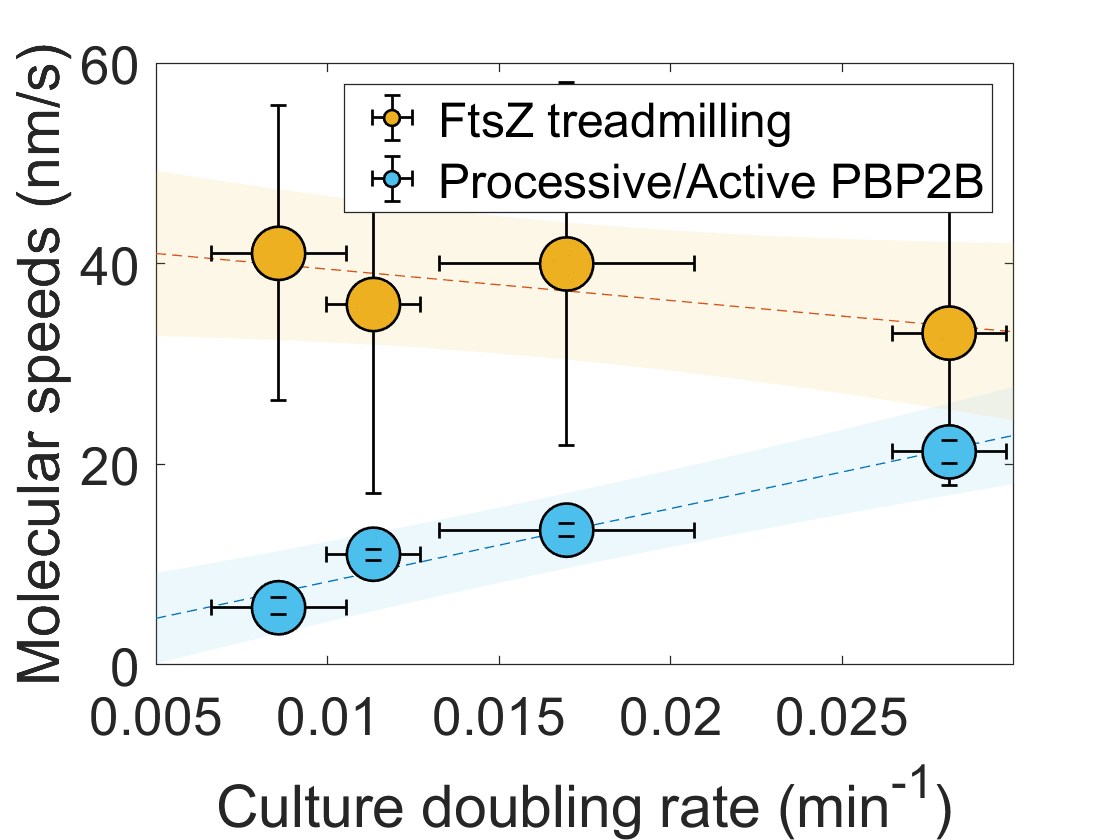

[p_2b, S_2b] = polyfit(Rd, spds2B, 1);
[p_Z, S_Z] = polyfit(Rd, spdsZ, 1);

[ploty_2b, delta_2b] = polyval(p_2b, plotx, S_2b);
[ploty_Z, delta_Z] = polyval(p_Z, plotx, S_Z);

SSR2b = sum((spds2B - (Rd*p_2b(1)+p_2b(2))).^2);
SSE2b = sum((spds2B - mean(spds2B)).^2);
R2_2b = 1 - SSR2b/SSE2b;

SSRZ = sum((spds2B - (Rd*p_2b(1)+p_2b(2))).^2);
SSEZ = sum((spdsZ - mean(spdsZ)).^2);
R2Z = 1 - SSRZ/SSEZ;

figure
hold on
patch([plotx fliplr(plotx)], [ploty_2b+2*delta_2b fliplr(ploty_2b-2*delta_2b)], [0.3 0.75 0.93], 'LineStyle', 'none', 'FaceAlpha', 0.1)
patch([plotx fliplr(plotx)], [ploty_Z+2*delta_Z fliplr(ploty_Z-2*delta_Z)], [0.93 0.69 0.13], 'LineStyle', 'none', 'FaceAlpha', 0.1)

plot(plotx, ploty_2b, '--')
plot(plotx, ploty_Z, '--')

h_Z = errorbar(Rd, spdsZ, spdsZ-spdsZerr, spdsZerr-spdsZ, Rderr, Rderr, 'ok', 'linew', 1, 'MarkerSize', 20, 'MarkerFaceColor', [0.93 0.69 0.13], 'DisplayName', 'FtsZ treadmilling');
h_2B = errorbar(Rd, spds2B, spds2B-spds2Berr_down, spds2Berr_up-spds2B, Rderr, Rderr, 'ok', 'linew', 1, 'MarkerSize', 20, 'MarkerFaceColor', [0.3 0.75 0.93], 'DisplayName', 'Processive/Active PBP2B');

xlabel('Culture doubling rate (min^{-1})')
ylabel('Molecular speeds (nm/s)')
xlim([0.005 0.03])
ylim([0 60])
set(gcf,'Color', [0.94 0.94 0.94])
set(gca,'box','on')
legend([h_Z h_2B])
set(gca,'FontSize',20)

## Nlinfit

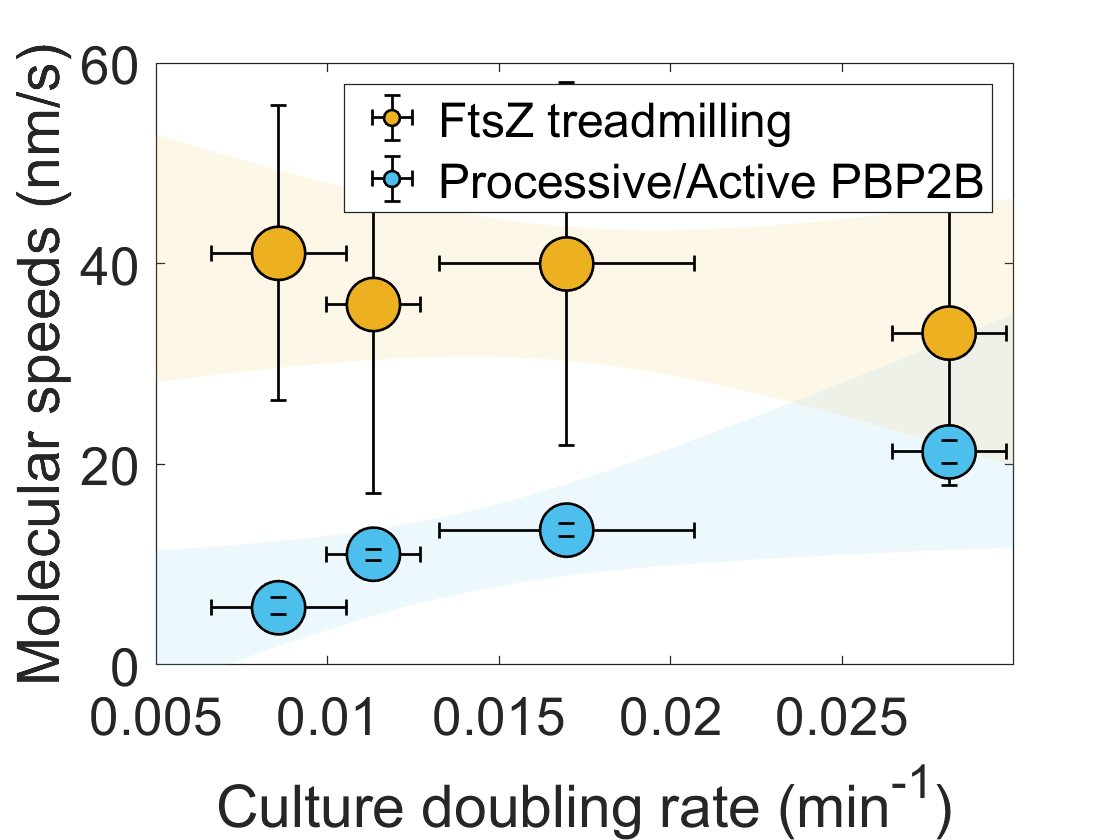

fitfun = @(a,x) a(1)*x + a(2);

[p_2b, R, J, CovB] = nlinfit(Rd, spds2B, fitfun, [100 0], 'Weights', 1./sqrt(Rderr.^2+spds2Berr.^2));
[p_Z, Rz, Jz, CovBz] = nlinfit(Rd, spdsZ, fitfun, [0 40], 'Weights', 1./sqrt(Rderr.^2+spdsZerr.^2));

[ploty_2b, delta_2b] = nlpredci(fitfun, plotx, p_2b, R, 'Covar', CovB);
[ploty_Z, delta_Z] = nlpredci(fitfun, plotx, p_Z, Rz, 'Covar', CovBz);

figure
hold on
patch([plotx fliplr(plotx)], [ploty_2b+delta_2b fliplr(ploty_2b-delta_2b)], [0.3 0.75 0.93], 'LineStyle', 'none', 'FaceAlpha', 0.1)
patch([plotx fliplr(plotx)], [ploty_Z+delta_Z fliplr(ploty_Z-delta_Z)], [0.93 0.69 0.13], 'LineStyle', 'none', 'FaceAlpha', 0.1)

h_Z = errorbar(Rd, spdsZ, spdsZ-spdsZerr, spdsZerr-spdsZ, Rderr, Rderr, 'ok', 'linew', 1, 'MarkerSize', 20, 'MarkerFaceColor', [0.93 0.69 0.13], 'DisplayName', 'FtsZ treadmilling');
h_2B = errorbar(Rd, spds2B, spds2B-spds2Berr_down, spds2Berr_up-spds2B, Rderr, Rderr, 'ok', 'linew', 1, 'MarkerSize', 20, 'MarkerFaceColor', [0.3 0.75 0.93], 'DisplayName', 'Processive/Active PBP2B');

xlabel('Culture doubling rate (min^{-1})')
ylabel('Molecular speeds (nm/s)')
xlim([0.005 0.03])
ylim([0 60])
set(gcf,'Color', [0.94 0.94 0.94])
set(gca,'box','on')
legend([h_Z h_2B])
set(gca,'FontSize',20)